clear
close all

winter = xlsread('Env1_superf_metadata.xlsx'); 



%%Defining variables: OJO Matlab no lee la primera fila que es texto, si quiero
%%hay funciones para hacerlo. EQUIDISTANCIA(0,207)

day = winter (:,1);

no3 = winter(:,4);
no2 = winter (:, 5);
nh4 = winter (:, 6);
TIN = winter (:, 7);
po4  = winter(:,8);
sio2 = winter(:,9);
Chla_3um = winter(:,10);
Chla_2um = winter(:,11);
chla_total = winter(:,12);

malla de colores para fluo

[x,y]= meshgrid(lonint,presint);

%INTERPOlo mis variables sobre la malla x,y que acabo de crear
TINint= griddata(lon_mean(isfinite(TIN_mean)),depth_mean(isfinite(TIN_mean)),TIN_mean(isfinite(TIN_mean)),x(1,:),y(:,1));
NO2int= griddata(lon_mean(isfinite(NO2_mean)),depth_mean(isfinite(NO2_mean)),NO2_mean(isfinite(NO2_mean)),x(1,:),y(:,1));
no3int= griddata(lon_mean(isfinite(no3_mean)),depth_mean(isfinite(no3_mean)),no3_mean(isfinite(no3_mean)),x(1,:),y(:,1));
nh4int= griddata(lon_mean(isfinite(nh4_mean)),depth_mean(isfinite(nh4_mean)),nh4_mean(isfinite(nh4_mean)),x(1,:),y(:,1));
po4int= griddata(lon_mean(isfinite(po4_mean)),depth_mean(isfinite(po4_mean)),po4_mean(isfinite(po4_mean)),x(1,:),y(:,1));
sio2int= griddata(lon_mean(isfinite(sio2_mean)),depth_mean(isfinite(sio2_mean)),sio2_mean(isfinite(sio2_mean)),x(1,:),y(:,1));
Chla_3umint= griddata(lon_mean(isfinite(Chla_3um_mean)),depth_mean(isfinite(Chla_3um_mean)),Chla_3um_mean(isfinite(Chla_3um_mean)),x(1,:),y(:,1));
Chla_2umint= griddata(lon_mean(isfinite(Chla_2um_mean)),depth_mean(isfinite(Chla_2um_mean)),Chla_2um_mean(isfinite(Chla_2um_mean)),x(1,:),y(:,1));
chla_totalint= griddata(lon_mean(isfinite(chla_total_mean)),depth_mean(isfinite(chla_total_mean)),chla_total_mean(isfinite(chla_total_mean)),x(1,:),y(:,1));


%OJO que la funcion pcolor por defecto elimina el ultimo perfil, se podria
%repetir ese ultimo pefil para solventar
TINint = [TINint,TINint(:,end)];
NO2int = [NO2int,NO2int(:,end)];
no3int = [no3int,no3int(:,end)];
nh4int = [nh4int,nh4int(:,end)];
po4int = [po4int,po4int(:,end)];
sio2int = [sio2int,sio2int(:,end)];
Chla_3umint = [Chla_3umint,Chla_3umint(:,end)];
Chla_2umint = [Chla_2umint,Chla_2umint(:,end)];
chla_totalint = [chla_totalint,chla_totalint(:,end)];


lonint=[lonint,lonint(:,end)+0.207];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%    Figuras 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Las figuras estan hechas con la funcion "contourf" y "scatter" para comparar
% la interpolacion (conturf = interpolacion VS scatter = datos reales)

## NO2 %%%

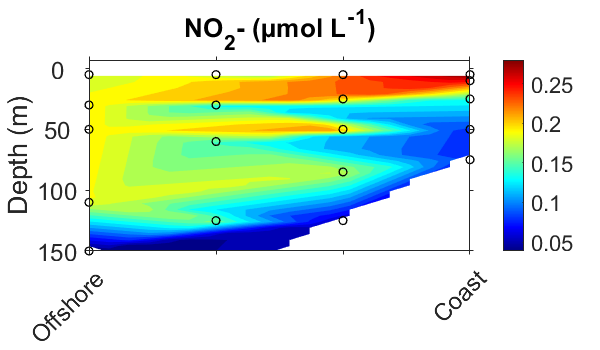

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

%lo que esta dentro del ultimo parentesis define cuantos saltos de color haces. En este caso. el no2 va de 0 a 0.35 y en el medio pones cada cuantwo queires cambiar de color
[C,h]=contourf(lonint, -presint, NO2int,(0:.01:0.5)); 
set(h,'color','none');
%map = brewermap(150,'*Spectral');
%mycolors = [1 1 1; 0 0 1; 0 1 1;  0 1 0; 1 1 0; 1 0 0; 1 0 1]; % RGB Triplet
colormap(jet);
cb=colorbar;


%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',12);
set(gca,'tickdir','out','Xtick',[-9.708 -9.432 -9.156 -8.88],'Xticklabel',[{ 'Offshore' '' '' 'Coast' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(NO2_mean)),-depth_mean(isfinite(NO2_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

title('NO_{2}^ - (µmol L^-^1)')
xlim([-9.708 -8.88])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

## NO3 %%%

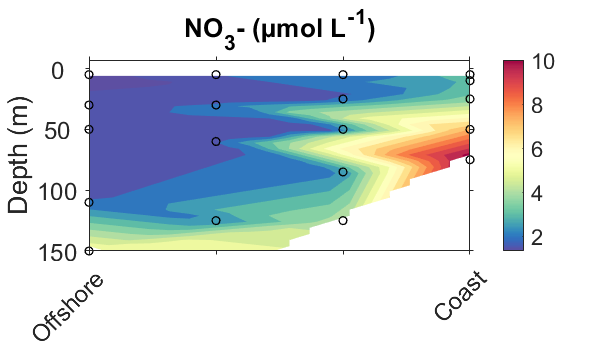

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

[C,h]=contourf(lonint, -presint, no3int,(0:.5:10)); 
set(h,'color','none');
map = brewermap(150,'*Spectral');
colormap(map);
cb=colorbar;

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',16);
set(gca,'tickdir','out','Xtick',[-9.708 -9.432 -9.156 -8.88],'Xticklabel',[{ 'Offshore' '' '' 'Coast' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(no3_mean)),-depth_mean(isfinite(no3_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

% Ajustamos los limites de lat y prof
title('NO_{3}^ - (µmol L^-^1)')
xlim([-9.708 -8.88])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

## NH4 %%

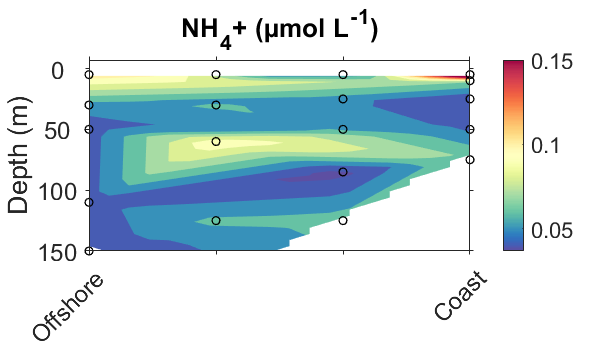

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

[C,h]=contourf(lonint, -presint, nh4int,(0:0.01:0.15)); 
set(h,'color','none');
map = brewermap(150,'*Spectral');
colormap(map);
cb=colorbar;

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',22);
set(gca,'tickdir','out','Xtick',[-9.708 -9.432 -9.156 -8.88],'Xticklabel',[{ 'Offshore' '' '' 'Coast' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(nh4_mean)),-depth_mean(isfinite(nh4_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);


% Ajustamos los limites de lat y prof
title('NH_{4}^ + (µmol L^-^1)')
xlim([-9.708 -8.88])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

## TIN %%%

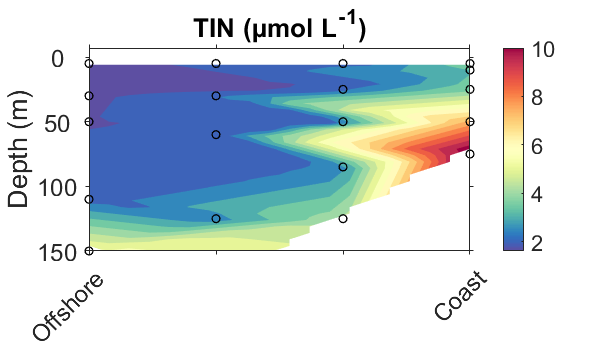

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

[C,h]=contourf(lonint, -presint, TINint, (0:.5:10));
set(h,'color','none');
map = brewermap(150,'*Spectral');
colormap(map);
cb=colorbar;

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',22);
set(gca,'tickdir','out','Xtick',[-9.708 -9.432 -9.156 -8.88],'Xticklabel',[{ 'Offshore' '' '' 'Coast' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(TIN_mean)),-depth_mean(isfinite(TIN_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

% Ajustamos los limites de lat y prof
title('TIN (µmol L^-^1)')
xlim([-9.708 -8.88])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

## PO4 %%%

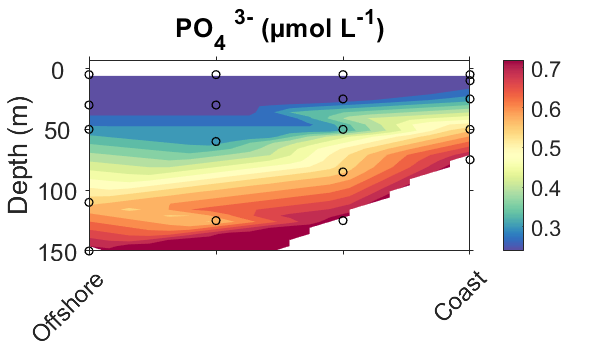

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

[C,h]=contourf(lonint, -presint, po4int, (0:0.03:1));
set(h,'color','none');
map = brewermap(150,'*Spectral');
colormap(map);
cb=colorbar;

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',22);
set(gca,'tickdir','out','Xtick',[-9.708 -9.432 -9.156 -8.88],'Xticklabel',[{ 'Offshore' '' '' 'Coast' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(po4_mean)),-depth_mean(isfinite(po4_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

% Ajustamos los limites de lat y prof
title('PO_{4} ^3^- (µmol L^-^1)')
xlim([-9.708 -8.88])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

## SiO2 %%%

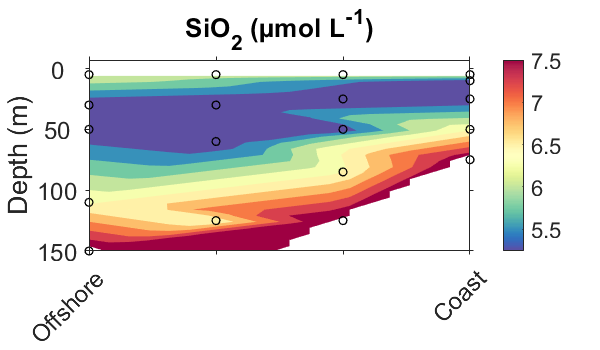

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

[C,h]=contourf(lonint, -presint, sio2int, (0:0.25:7.5)); %%AQUI ESTA EL DETALLE DE LA ESCALE
set(h,'color','none');
map = brewermap(150,'*Spectral');
colormap(map);
cb=colorbar;

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',22);
set(gca,'tickdir','out','Xtick',[-9.708 -9.432 -9.156 -8.88],'Xticklabel',[{ 'Offshore' '' '' 'Coast' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(sio2_mean)),-depth_mean(isfinite(sio2_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

% Ajustamos los limites de lat y prof
title('SiO_{2} (µmol L^-^1)')
xlim([-9.708 -8.88])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

## Chl-a Total %%%

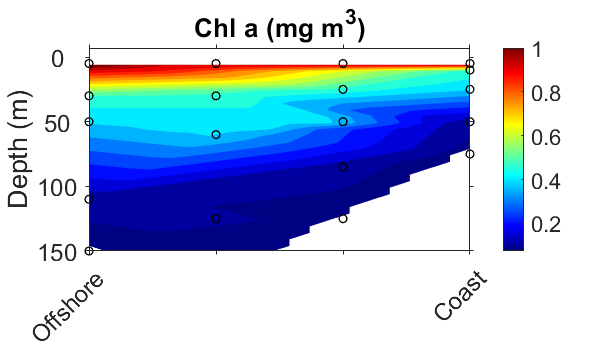

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

[C,h]=contourf(lonint, -presint, chla_totalint, (0:0.05:1)); % limites 
set(h,'color','none');
%map = brewermap(150,'*Spectral');
%mycolors = [1 1 1; 0 0 1; 0 1 1;  0 1 0; 1 1 0; 1 0 0; 1 0 1]; % RGB Triplet
colormap(jet);
cb=colorbar;

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',22);
set(gca,'tickdir','out','Xtick',[-9.708 -9.432 -9.156 -8.88],'Xticklabel',[{ 'Offshore' '' '' 'Coast' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(chla_total_mean)),-depth_mean(isfinite(chla_total_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

% Ajustamos los limites de lat y prof
title('Chl a (mg m^3)')
xlim([-9.708 -8.88])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)